%%%%%%%%%%%%%%%%%%%%%%%%%%%%％％％％％％％%%%%%
% ch 50直下のピクセルにフォーカスをかける．
% フォーカス深度を１グリッドずつ変化させて，開口合成受信データを生成する．
% F値を固定する．最近接距離をいくつに設定する？
% x-axis: 20 mmのときに全素子を使うという前提を設ける．
% 対象にする媒質データ：case26を用いる．
% IMCL割合を0 %に固定する．
% kgrid.x_vec が0となるのは251番目の要素．
% グリッド幅が0.1 mm
% 素子間ピッチが0.4 mm
% よって，最近接深度(最近接距離は0.4 mm)
% 深度ごとの細かい素子割当は，floor()を用いる．
% 整相加算の際に参照する音速を1580 m/sとする．
% 整相加算の前に参照点と受信chごとの振幅(ヒルベルト変換後絶対値)最大値との距離の
% 合計を評価関数として媒質の均質性を評価することも同時に行う．
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clear;
load("H:\data\kwave\config\t_pos_2board.mat");
load("H:\data\kwave\result\2018_10_21_highFrequency_variousIMCL\case26_IMCL4.0_5MHz\rfdata.mat");
load("H:\data\kwave\result\2018_10_21_highFrequency_variousIMCL\case26_IMCL4.0_5MHz\medium.mat");
load("H:\data\kwave\result\2018_10_21_highFrequency_variousIMCL\case26_IMCL4.0_5MHz\kgrid.mat");
load("H:\data\kwave\result\2018_10_21_highFrequency_variousIMCL\case26_IMCL4.0_5MHz\sourse_wave.mat");
% load("H:\data\kwave\result\2018_10_21_point_medium\point_mudium5MHz\rfdata.mat");
% load("H:\data\kwave\result\2018_10_21_point_medium\point_mudium5MHz\medium.mat");
% load("H:\data\kwave\result\2018_10_21_point_medium\point_mudium5MHz\kgrid.mat");
% load("H:\data\kwave\result\2018_10_21_point_medium\point_mudium5MHz\sourse_wave.mat");

% 初期設定
v_fat = 1450;%[m/s]
v_muscle = 1580;%[m/s]
t_facing_distance = 0.04;%[m]
rate_IMCL = [0,2,4,6,8,10,12,14];
num_depth = (t_pos(2,1)-t_pos(2,101))/kgrid.dx - 3;%'3'とあるのは，最近接距離が0.4 mmであることを考慮している．
focal_depth = zeros(1,num_depth);
[num_sample,num_receiver,num_transmitter] = size(rfdata);
num_echo_receiver = num_transmitter;
reference_point = zeros(num_echo_receiver,num_depth);
reference_point_lowerlimit = zeros(num_echo_receiver,num_depth);%均質性評価のためのRFデータマスキングに使う
reference_point_upperlimit = zeros(num_echo_receiver,num_depth);%均質性評価のためのRFデータマスキングに使う
point_maxAmp_in_mask = zeros(num_echo_receiver,num_depth);%マスク処理後のRFデータで振幅最大のサンプル点情報
distance_from_focal_point_all = zeros(1,num_echo_receiver);
focal_signal_total = zeros(length(rate_IMCL),num_depth);
focal_signal_total2 = zeros(length(rate_IMCL),num_depth);
% focal_phase_total = zeros(length(rate_IMCL),num_depth);
focal_amp = zeros(length(rate_IMCL),num_depth,num_echo_receiver);
% focal_phase = zeros(length(rate_IMCL),num_depth,num_echo_receiver);
homogeneity_percel = zeros(length(rate_IMCL),num_depth,num_echo_receiver);
homogeneity_total = zeros(length(rate_IMCL),num_depth);

for kk = 1:length(rate_IMCL)
    v_reference = v_muscle*(1-rate_IMCL(kk)/100) + v_fat*(rate_IMCL(kk)/100);
    focused_rfdata = zeros(num_sample,num_echo_receiver,num_depth);
    focused_rfdata_amp = zeros(num_sample,num_echo_receiver,num_depth);
    %     focused_rfdata_phase = zeros(num_sample,num_echo_receiver,num_depth);
    focused_rfdata_amp_masked = zeros(num_sample,num_echo_receiver,num_depth);
    for ii = 1:num_depth
        focal_depth(1,ii) = (ii+3)*kgrid.dx;
        focal_point = [0;t_pos(2,1)-focal_depth(1,ii)];
        target_element = find((-focal_depth(1,ii)/2<=t_pos(1,1:100)&(t_pos(1,1:100)<=focal_depth(1,ii)/2)));
        distance_from_focal_point = zeros(1,length(target_element));
        %受信用の参照点算出
        for jj = 1:num_echo_receiver
            distance_from_focal_point_all(1,jj) = norm(t_pos(:,jj) - focal_point);
            delay_time_all = round(((distance_from_focal_point_all - focal_depth(1,ii))/v_reference)/kgrid.dt);%[sample]
            reference_point(jj,ii) = round(delay_time_all(1,jj)+1+(2*focal_depth(1,ii)/v_reference)/kgrid.dt+25);
            %25はfocal_amplitudeを最大にするオフセット．
            reference_point_lowerlimit(jj,ii) ...
                = round(delay_time_all(1,jj)*(v_reference/v_muscle)+1+(2*focal_depth(1,ii)/v_muscle)/kgrid.dt+25-1);
            reference_point_upperlimit(jj,ii) ...
                = round(delay_time_all(1,jj)*(v_reference/v_fat)+1+(2*focal_depth(1,ii)/v_fat)/kgrid.dt+25);
            %どんなに遅延しても早く到達してもこの範囲内に焦点位置からのエコーパルスが入っているであろう上限・下限
        end
        %送信ビームフォーミング（共通）
        for jj = 1:length(target_element)
            distance_from_focal_point(1,jj) = distance_from_focal_point_all(1,target_element(jj));
            % 遅延処理
            delay_time = delay_time_all(1,target_element(jj));%[sample]
            read_range_rfdata = length(delay_time+1:num_sample);
            focused_rfdata(1:read_range_rfdata,:,ii) = focused_rfdata(1:read_range_rfdata,:,ii)...
                +  rfdata(delay_time+1:num_sample,1:100,target_element(jj));%整相加算
        end
        hilb_rfdata = hilbert(focused_rfdata(:,:,ii));
        focused_rfdata_amp(:,:,ii) = abs(hilb_rfdata);
        %         focused_rfdata_phase(:,:,ii) = atan(imag(hilb_rfdata)./real(hilb_rfdata));
        focused_rfdata_amp_masked(:,:,ii) = focused_rfdata_amp(:,:,ii);
        %RFデータマスキング（均質性評価のため）
        for jj = 1:num_echo_receiver
            focused_rfdata_amp_masked(1:reference_point_lowerlimit(jj,ii),jj,ii) = 0;
            focused_rfdata_amp_masked(reference_point_upperlimit(jj,ii):end,jj,ii) = 0;
        end
        [~,point_maxAmp_in_mask(:,ii)] = max(focused_rfdata_amp_masked(:,:,ii),[],1);
        for jj = 1:length(target_element)
            %受信ビームフォーミング（整相加算のため）
            focal_signal_total(kk,ii) = focal_signal_total(kk,ii)+ ...
                focused_rfdata_amp(reference_point(target_element(1,jj),ii),target_element(1,jj),ii)/length(target_element);
            focal_signal_total2(kk,ii) = focal_signal_total2(kk,ii)+ ...
                focused_rfdata(reference_point(target_element(1,jj),ii),target_element(1,jj),ii)/length(target_element);
            focal_amp(kk,ii,target_element(jj)) = ...
                focused_rfdata_amp(reference_point(target_element(1,jj),ii),target_element(1,jj),ii)/length(target_element);
            %             tmp = focused_rfdata_phase(reference_point(target_element(1,jj),ii),target_element(1,jj),ii);
            %             focal_phase(kk,ii,target_element(jj)) = tmp;
            %             focal_phase_total(kk,ii) = focal_phase_total(kk,ii) + sin(tmp);
            %均質性評価指標
            homogeneity_percel(kk,ii,jj) = abs(point_maxAmp_in_mask(jj,ii) - reference_point(jj,ii));
        end
        homogeneity_total(kk,ii) = sum(homogeneity_percel(kk,ii,:))/length(target_element);
        %         focal_signal(kk,ii) = abs(hilbert(focal_signal(kk,ii)));
    end
end

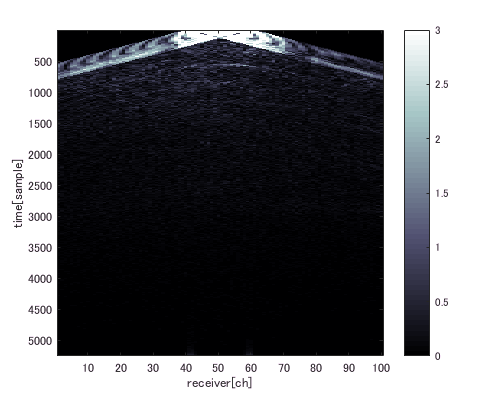

figure;
imagesc(focused_rfdata_amp(:,:,76));
xlabel('receiver[ch]');
ylabel('time[sample]');
colormap(bone);
colorbar;
caxis([0 3]);
axis square;
exportfig("H:\result\2018_10_21_search_path_contain_only_IMCL\focused_rfdata_amp_boundary",'png',[500,400]);

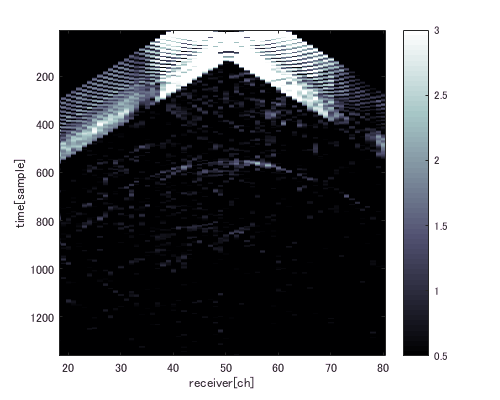

figure;
imagesc(focused_rfdata_amp(:,:,76));
xlabel('receiver[ch]');
ylabel('time[sample]');
colormap(bone);
colorbar;
caxis([0.5 3]);
axis square;
xlim([18.2 80.3])
ylim([9 1362])
exportfig("H:\result\2018_10_21_search_path_contain_only_IMCL\focused_rfdata_amp_boundary_detail",'png',[500,400]);

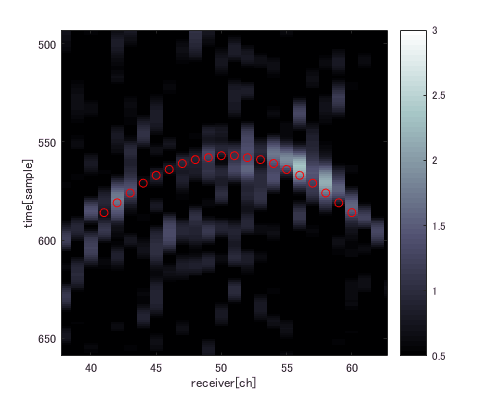

figure;
imagesc(focused_rfdata_amp(:,:,76));
xlabel('receiver[ch]');
ylabel('time[sample]');
colormap(bone);
colorbar;
caxis([0.5 3]);
axis square;
xlim([37.7 62.7])
ylim([493 659])
hold on
scatter(41:60,reference_point(41:60,76),'red');
exportfig("H:\result\2018_10_21_search_path_contain_only_IMCL\focused_rfdata_amp_boundary_detail_marked",'png',[500,400]);

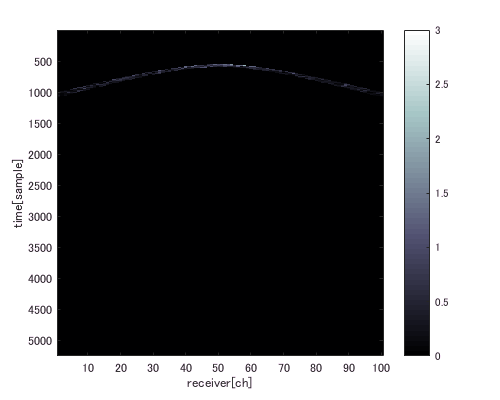

figure;
imagesc(focused_rfdata_amp_masked(:,:,76));
xlabel('receiver[ch]');
ylabel('time[sample]');
colormap(bone);
colorbar;
caxis([0 3]);
axis square;
exportfig("H:\result\2018_10_21_search_path_contain_only_IMCL\focused_rfdata_amp_boundary_mask",'png',[500,400]);

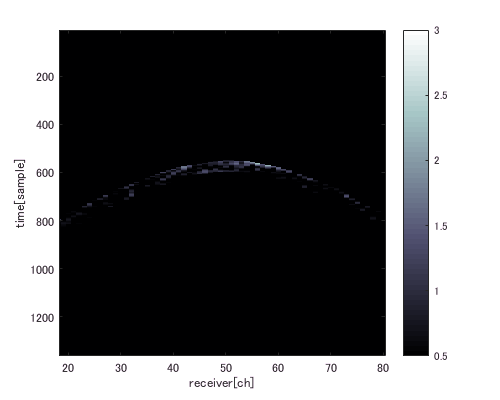

figure;
imagesc(focused_rfdata_amp_masked(:,:,76));
xlabel('receiver[ch]');
ylabel('time[sample]');
colormap(bone);
colorbar;
caxis([0.5 3]);
axis square;
xlim([18.2 80.3])
ylim([9 1362])
exportfig("H:\result\2018_10_21_search_path_contain_only_IMCL\focused_rfdata_amp_boundary_detail_mask",'png',[500,400]);

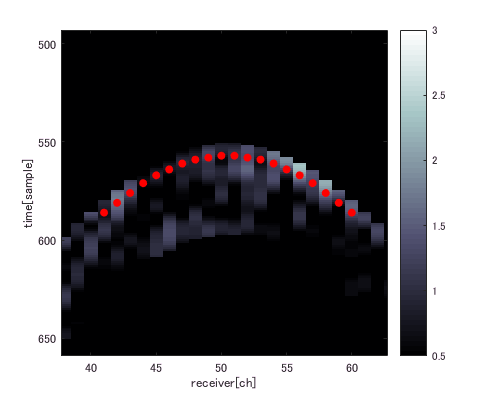

figure;
imagesc(focused_rfdata_amp_masked(:,:,76));
xlabel('receiver[ch]');
ylabel('time[sample]');
colormap(bone);
colorbar;
caxis([0.5 3]);
axis square;
xlim([37.7 62.7])
ylim([493 659])
hold on
scatter(41:60,reference_point(41:60,76),'red','filled');
exportfig("H:\result\2018_10_21_search_path_contain_only_IMCL\focused_rfdata_amp_boundary_detail_marked_mask",'png',[500,400]);

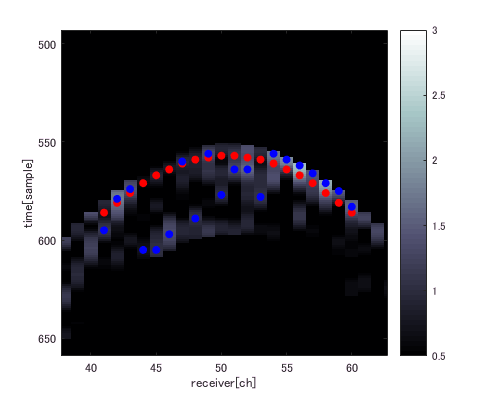

figure;
imagesc(focused_rfdata_amp_masked(:,:,76));
xlabel('receiver[ch]');
ylabel('time[sample]');
colormap(bone);
colorbar;
caxis([0.5 3]);
axis square;
xlim([37.7 62.7])
ylim([493 659])
hold on
scatter(41:60,reference_point(41:60,76),'red','filled');
scatter(41:60,point_maxAmp_in_mask(41:60,76),'blue','filled');
exportfig("H:\result\2018_10_21_search_path_contain_only_IMCL\focused_rfdata_amp_boundary_detail_marked_mask_maxpoint",'png',[500,400]);

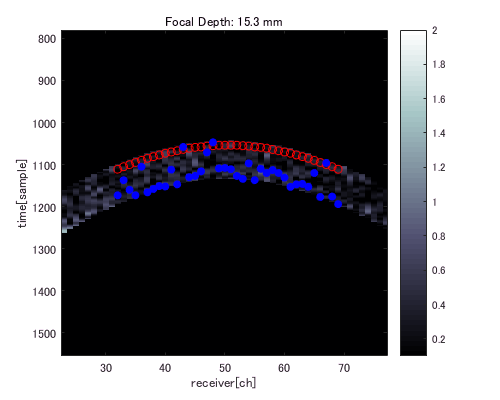

figure;
imagesc(focused_rfdata_amp_masked(:,:,150));
xlabel('receiver[ch]');
ylabel('time[sample]');
colormap(bone);
colorbar;
caxis([0.1 2]);
axis square;
hold on
scatter(32:69,reference_point(32:69,150),'red');
scatter(32:69,point_maxAmp_in_mask(32:69,150),'blue','filled');
xlim([22.5 77.2])
ylim([780 1555])
title('Focal Depth: 15.3 mm')
exportfig("H:\result\2018_10_21_search_path_contain_only_IMCL\focused_rfdata_amp_boundary_detail_marked_mask_maxpoint_15.3mm",'png',[500,400]);

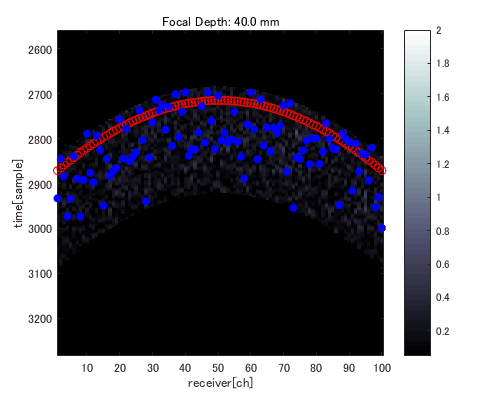

figure;
imagesc(focused_rfdata_amp_masked(:,:,397));
xlabel('receiver[ch]');
ylabel('time[sample]');
colormap(bone);
colorbar;
caxis([0.05 2]);
axis square;
hold on
scatter(1:100,reference_point(:,397),'red');
scatter(1:100,point_maxAmp_in_mask(:,397),'blue','filled');
xlim([1.0 100.5])
ylim([2558 3284])
title('Focal Depth: 40.0 mm')
exportfig("H:\result\2018_10_21_search_path_contain_only_IMCL\focused_rfdata_amp_boundary_detail_marked_mask_maxpoint_40.0mm",'png',[500,400]);

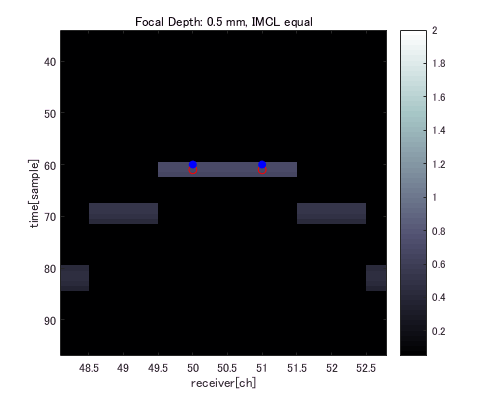

figure;
imagesc(focused_rfdata_amp_masked(:,:,2));
xlabel('receiver[ch]');
ylabel('time[sample]');
colormap(bone);
colorbar;
caxis([0.05 2]);
axis square;
hold on
scatter(50:51,reference_point(50:51,2),'red');
scatter(50:51,point_maxAmp_in_mask(50:51,2),'blue','filled');
xlim([48.1 52.8])
ylim([34 97])
title('Focal Depth: 0.5 mm, IMCL equal')
exportfig("H:\result\2018_10_21_search_path_contain_only_IMCL\focused_rfdata_amp_boundary_detail_marked_mask_maxpoint_0.5mm_IMCLequal",'png',[500,400]);

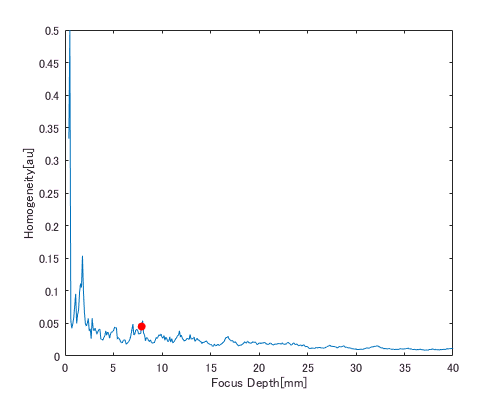

figure;
plot(focal_depth*1000,1./homogeneity_total(3,:));
xlabel('Focus Depth[mm]');
ylabel('Homogeneity[au]');
hold on
scatter(focal_depth(1,76)*1000,1/homogeneity_total(3,76),'red','filled');
exportfig("H:\result\2018_10_21_search_path_contain_only_IMCL\homogeneity_IMCL4%_equal",'png',[500,400]);

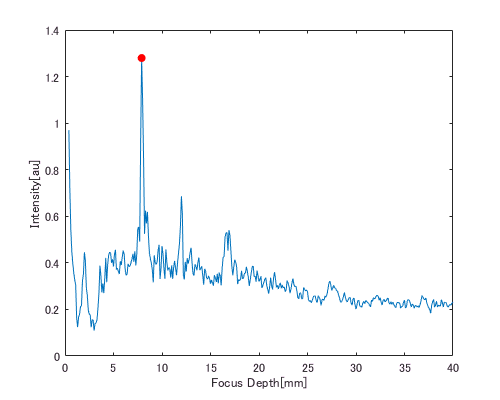

figure;
plot(focal_depth*1000,focal_signal_total(3,:));
hold on
scatter(focal_depth(1,76)*1000,focal_signal_total(3,76),'red','filled');
xlabel('Focus Depth[mm]');
ylabel('Intensity[au]');
exportfig("H:\result\2018_10_21_search_path_contain_only_IMCL\focal_signal_total_amp_IMCL4%_equal",'png',[500,400]);

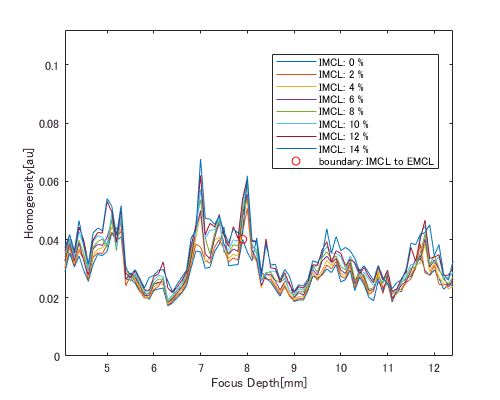

figure;
for ii = 1:8
    plot(focal_depth*1000,1./homogeneity_total(ii,:));
    xlabel('Focus Depth[mm]');
    ylabel('Homogeneity[au]');
    hold on
    xlim([4.1 12.4])
    ylim([0.000 0.112])
end
scatter(focal_depth(1,76)*1000,1/homogeneity_total(1,76),'r');
legend('IMCL: 0 %','IMCL: 2 %','IMCL: 4 %','IMCL: 6 %','IMCL: 8 %','IMCL: 10 %','IMCL: 12 %','IMCL: 14 %','boundary: IMCL to EMCL','Location','best');
exportfig("H:\result\2018_10_21_search_path_contain_only_IMCL\homogeneity_IMCL_various",'png',[500,400]);

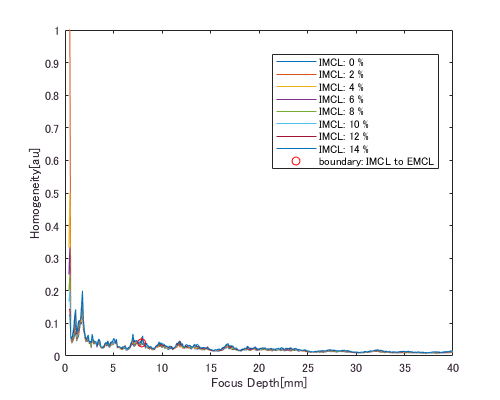

figure;
for ii = 1:8
    plot(focal_depth*1000,1./homogeneity_total(ii,:));
    xlabel('Focus Depth[mm]');
    ylabel('Homogeneity[au]');
    hold on
end
scatter(focal_depth(1,76)*1000,1/homogeneity_total(1,76),'r');
legend('IMCL: 0 %','IMCL: 2 %','IMCL: 4 %','IMCL: 6 %','IMCL: 8 %','IMCL: 10 %','IMCL: 12 %','IMCL: 14 %','boundary: IMCL to EMCL','Location','best');
exportfig("H:\result\2018_10_21_search_path_contain_only_IMCL\homogeneity_IMCL_various_whole",'png',[500,400]);

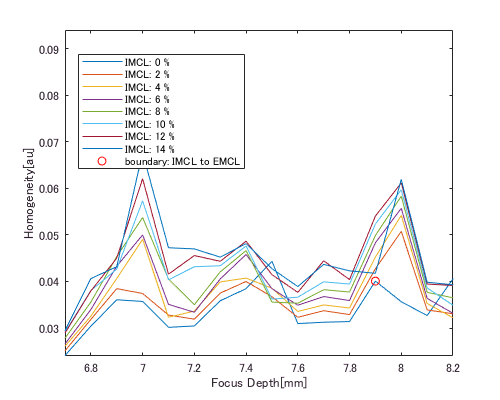

figure;
for ii = 1:8
    plot(focal_depth*1000,1./homogeneity_total(ii,:));
    xlabel('Focus Depth[mm]');
    ylabel('Homogeneity[au]');
    hold on
    xlim([6.7 8.2])
    ylim([0.024 0.094])
end
scatter(focal_depth(1,76)*1000,1/homogeneity_total(1,76),'r');
legend('IMCL: 0 %','IMCL: 2 %','IMCL: 4 %','IMCL: 6 %','IMCL: 8 %','IMCL: 10 %','IMCL: 12 %','IMCL: 14 %','boundary: IMCL to EMCL','Location','best');
exportfig("H:\result\2018_10_21_search_path_contain_only_IMCL\homogeneity_IMCL_various_detail",'png',[500,400]);

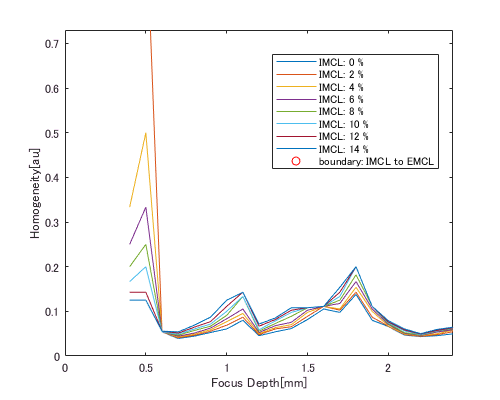

figure;
for ii = 1:8
    plot(focal_depth*1000,1./homogeneity_total(ii,:));
    xlabel('Focus Depth[mm]');
    ylabel('Homogeneity[au]');
    hold on
    xlim([0.0 2.4])
    ylim([0.000 0.730])
end
scatter(focal_depth(1,76)*1000,1/homogeneity_total(1,76),'r');
legend('IMCL: 0 %','IMCL: 2 %','IMCL: 4 %','IMCL: 6 %','IMCL: 8 %','IMCL: 10 %','IMCL: 12 %','IMCL: 14 %','boundary: IMCL to EMCL','Location','best');
exportfig("H:\result\2018_10_21_search_path_contain_only_IMCL\homogeneity_IMCL_various_detail2",'png',[500,400]);

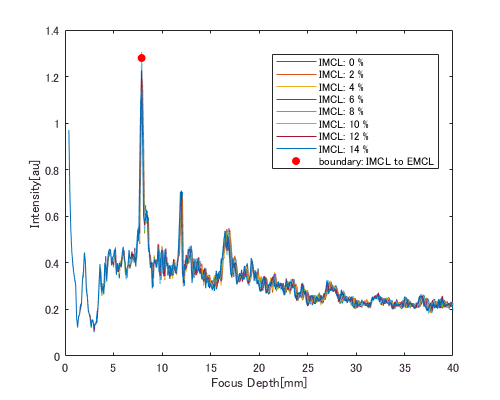

figure;
for ii = 1:8
    plot(focal_depth*1000,focal_signal_total(ii,:));
    hold on
end
scatter(focal_depth(1,76)*1000,focal_signal_total(3,76),'red','filled');
legend('IMCL: 0 %','IMCL: 2 %','IMCL: 4 %','IMCL: 6 %','IMCL: 8 %','IMCL: 10 %','IMCL: 12 %','IMCL: 14 %','boundary: IMCL to EMCL','Location','best');
xlabel('Focus Depth[mm]');
ylabel('Intensity[au]');
exportfig("H:\result\2018_10_21_search_path_contain_only_IMCL\focal_signal_total_amp_IMCL_various",'png',[500,400]);

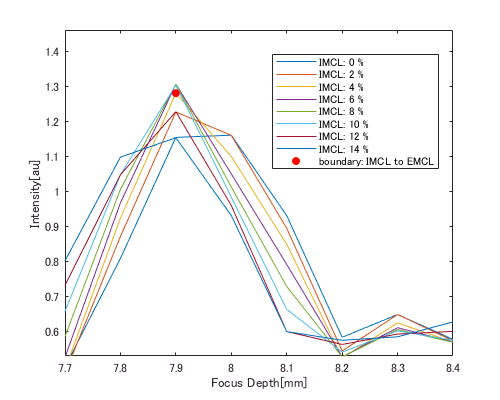

figure;
for ii = 1:8
    plot(focal_depth*1000,focal_signal_total(ii,:));
    hold on
end
scatter(focal_depth(1,76)*1000,focal_signal_total(3,76),'red','filled');
legend('IMCL: 0 %','IMCL: 2 %','IMCL: 4 %','IMCL: 6 %','IMCL: 8 %','IMCL: 10 %','IMCL: 12 %','IMCL: 14 %','boundary: IMCL to EMCL','Location','best');
xlabel('Focus Depth[mm]');
ylabel('Intensity[au]');
xlim([7.7 8.4])
ylim([0.53 1.46])
exportfig("H:\result\2018_10_21_search_path_contain_only_IMCL\focal_signal_total_amp_IMCL_various_detail",'png',[500,400]);

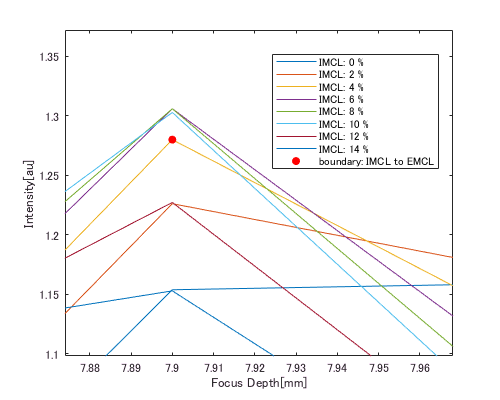

figure;
for ii = 1:8
    plot(focal_depth*1000,focal_signal_total(ii,:));
    hold on
end
scatter(focal_depth(1,76)*1000,focal_signal_total(3,76),'red','filled');
legend('IMCL: 0 %','IMCL: 2 %','IMCL: 4 %','IMCL: 6 %','IMCL: 8 %','IMCL: 10 %','IMCL: 12 %','IMCL: 14 %','boundary: IMCL to EMCL','Location','best');
xlabel('Focus Depth[mm]');
ylabel('Intensity[au]');
xlim([7.874 7.968])
ylim([1.098 1.372])
exportfig("H:\result\2018_10_21_search_path_contain_only_IMCL\focal_signal_total_amp_IMCL_various_detail2",'png',[500,400]);